**UVP light unit calibration** Version 2018/11/23

clear all; close all

## DATE analyse

disp(datestr(now,31))

2020-03-12 22:09:03


## PEOPLE analyse

people = input('Enter people first and last name (Marc Picheral) ','s');
if isempty(people); people = 'Marc Picheral'; end
disp(['Processing operator : ' char(people)]);

Processing operator : Marc Picheral


## IMAGE DATA

disp('Select folder (snXXX\eclairage_caracterisation\YYYYMMDD_HHMM_ver01_ver02) ')

Select folder (snXXX\eclairage_caracterisation\YYYYMMDD_HHMM_ver01_ver02) 


disp('containing the 2 light image folders and the background_image.tiff file ' );

containing the 2 light image folders and the background_image.tiff file 


drive_root = uigetdir('Select directory');

## Image acquisition date, UVP serial number & light numbers

aa = findstr(drive_root,'\');
date_vue = drive_root(aa(end)+1:end);year = date_vue(1:4);month = date_vue(5:6);
day = date_vue(7:8);
list_dir = dir(drive_root);uvp5sn = drive_root(aa(end-2)+1 : aa(end-1)-1);
ata = find([list_dir(1:end).isdir] == 1);
index_ver1 = ata(end-1); index_ver2 = ata(end);

## Settings

[pxs,px,orient,longmm,large,longpx,uvp,a,b,c,d,level,cor_img,img_ref_size] = somme_eclairage_settings(uvp5sn);

## Matrice de correction vignetage

corr_matrix = get_correction_matrix(drive_root);

--------- Reading correction matrix ------------


## Process first light

verrine01 = list_dir(index_ver1).name;disp(['Light : ',char(verrine01)])

Light : h002


[base1,Centre1]= Calculs_eclairages_uvp5_tr_param([list_dir(index_ver1).folder...
    ,'\',list_dir(index_ver1).name,'\'],a,b,c,d,level,cor_img,img_ref_size,corr_matrix);

Rep = W:\UVP5\Instruments\sn002\eclairage_caracterisation\20200309_1200_h002_h029\h002\
Image : 1 : W:\UVP5\Instruments\sn002\eclairage_caracterisation\20200309_1200_h002_h029\h002\\Basler_acA2040-25gm__21745209__20200309_122847799_0001.tiff
Image : 2 : W:\UVP5\Instruments\sn002\eclairage_caracterisation\20200309_1200_h002_h029\h002\\Basler_acA2040-25gm__21745209__20200309_122853436_0001.tiff
Image : 3 : W:\UVP5\Instruments\sn002\eclairage_caracterisation\20200309_1200_h002_h029\h002\\Basler_acA2040-25gm__21745209__20200309_122900747_0001.tiff
Image : 4 : W:\UVP5\Instruments\sn002\eclairage_caracterisation\20200309_1200_h002_h029\h002\\Basler_acA2040-25gm__21745209__20200309_122909372_0001.tiff
Image : 5 : W:\UVP5\Instruments\sn002\eclairage_caracterisation\20200309_1200_h002_h029\h002\\Basler_acA2040-25gm__21745209__20200309_122917203_0001.tiff
Image : 6 : W:\UVP5\Instruments\sn002\eclairage_caracterisation\20200309_1200_h002_h029\h002\\Basler_acA2040-25gm__21745209__20200309_12292511

## Process second light

verrine02 = list_dir(index_ver2).name;disp(['Light : ',char(verrine02)])

Light : h029


[base2,Centre2] = Calculs_eclairages_uvp5_tr_param([list_dir(index_ver2).folder...
    ,'\',list_dir(index_ver2).name,'\'],a,b,c,d,level,cor_img,img_ref_size,corr_matrix);

Rep = W:\UVP5\Instruments\sn002\eclairage_caracterisation\20200309_1200_h002_h029\h029\
Image : 1 : W:\UVP5\Instruments\sn002\eclairage_caracterisation\20200309_1200_h002_h029\h029\\Basler_acA2040-25gm__21745209__20200309_122704958_0001.tiff
Image : 2 : W:\UVP5\Instruments\sn002\eclairage_caracterisation\20200309_1200_h002_h029\h029\\Basler_acA2040-25gm__21745209__20200309_122710749_0001.tiff
Image : 3 : W:\UVP5\Instruments\sn002\eclairage_caracterisation\20200309_1200_h002_h029\h029\\Basler_acA2040-25gm__21745209__20200309_122717666_0001.tiff
Image : 4 : W:\UVP5\Instruments\sn002\eclairage_caracterisation\20200309_1200_h002_h029\h029\\Basler_acA2040-25gm__21745209__20200309_122724403_0001.tiff
Image : 5 : W:\UVP5\Instruments\sn002\eclairage_caracterisation\20200309_1200_h002_h029\h029\\Basler_acA2040-25gm__21745209__20200309_122731082_0001.tiff
Image : 6 : W:\UVP5\Instruments\sn002\eclairage_caracterisation\20200309_1200_h002_h029\h029\\Basler_acA2040-25gm__21745209__20200309_12273789

## Separated lights and resulting data files proces

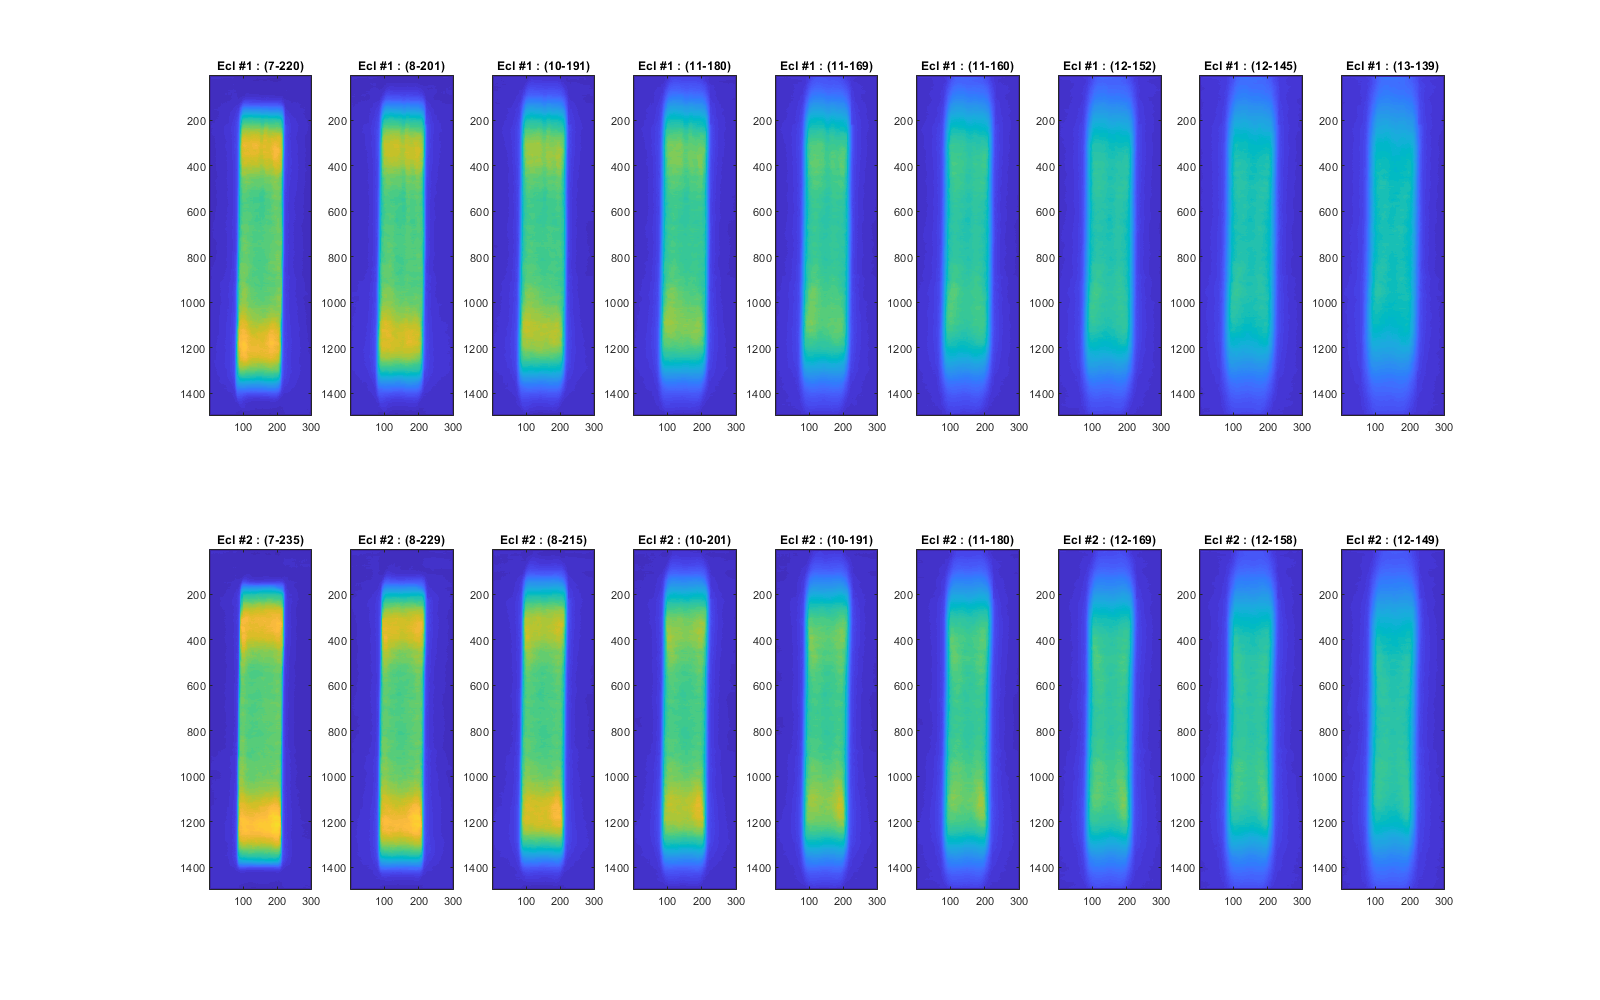

Figure_2_lights(base1,base2,date_vue,drive_root,uvp5sn,verrine01,verrine02)

## Process total volume

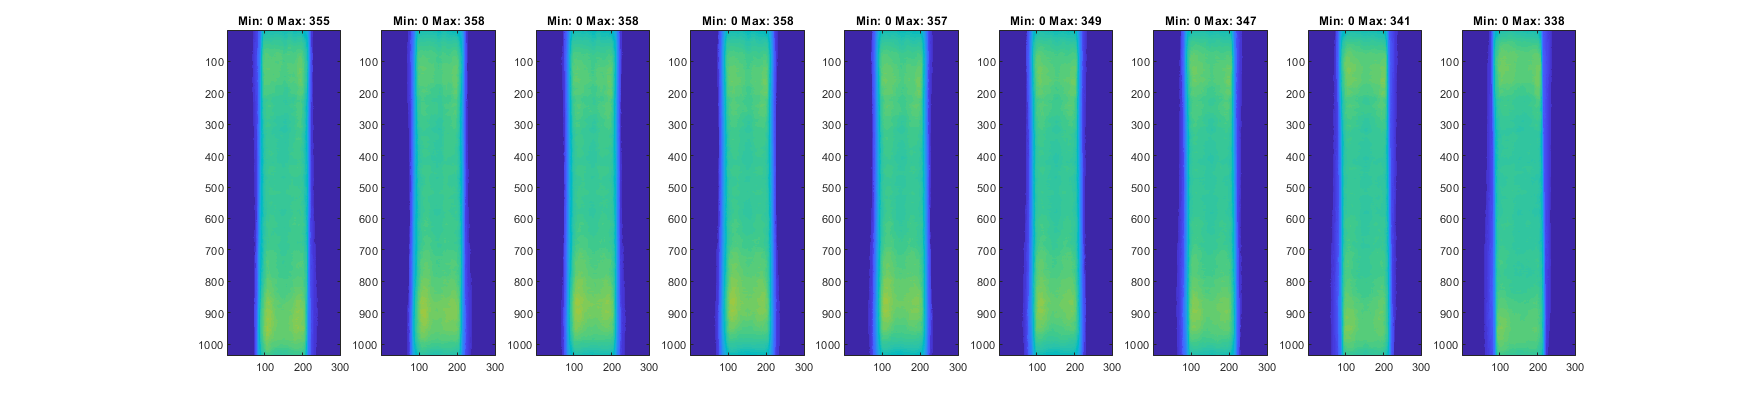

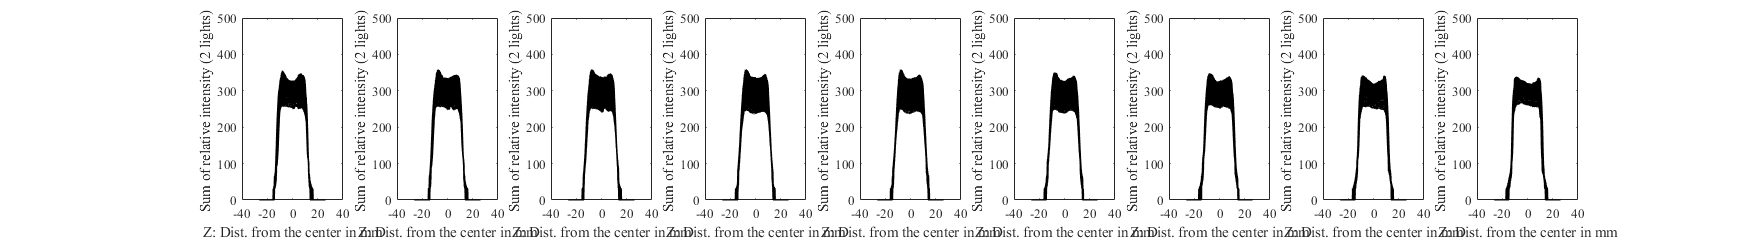

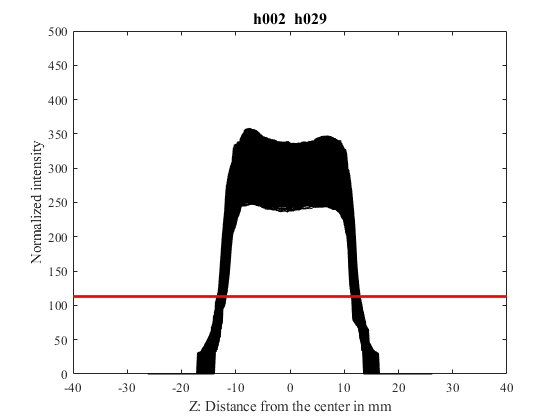

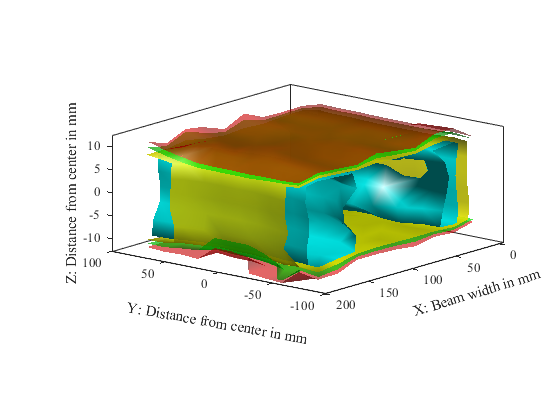

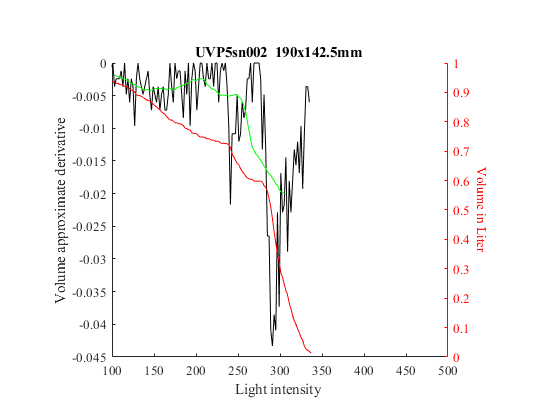

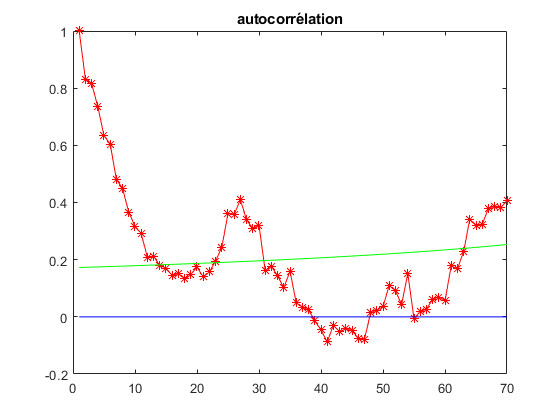

[b max_int vol vol_100 cor_int seuil_vol_fixe] = Somme_eclairage_new_corr...
    (uvp5sn,drive_root,base1,base2,longpx,large,px,longmm,verrine01,verrine02...
    ,a,b,c,d,img_ref_size,cor_img,Centre1,Centre2);

## Resulting data

Somme_images_results(drive_root,uvp5sn,date_vue,verrine01,verrine02,large,longmm,...
    b,max_int,vol,vol_100,cor_int,level,cor_img,base1,base2,seuil_vol_fixe)

UVP=       UVP5sn002
Date_img=           20200309_1200_h002_h029
light_1=            h002
light_1 (I_mean) =  131.1027
light_1 (I_min) =   108.701
light_1 (I_max) =   155.6309
light_2=            h029
light_2 (I_mean) =  139.9194
light_2 (I_min) =   118.032
light_2 (I_max) =   160.5551
Mean uncorrected Intensity (light1 + Light2) =  302
X=                  142.5
Y=                  190
Volume_s113=        0.85916
Z=                  31.7325
I_mean (mean int of all img) =            351
I_min (min int of all img) =              338
I_max (max int of all img) =              358
I_cor=              1
Img_range=          16
Img_step=           2
